clear

## Run other scripts

Parameters_avr_power;

Model_Atmospheric_turbulence;

Model_Channel_state_thes;

sol = 1.1925e-07

sol = 1.2994e-07

sol = 1.4214e-07

sol = 1.5588e-07

sol = 1.7113e-07

sol = 1.8639e-07

sol = 2.0318e-07

sol = 2.2149e-07

sol = 2.4132e-07

sol = 2.6421e-07

sol = 2.8863e-07

sol = 3.1609e-07

sol = 3.4508e-07

sol = 3.7713e-07

sol = 4.1222e-07

sol = 4.5037e-07

sol = 4.9309e-07

sol = 5.3887e-07

sol = 5.8922e-07

sol = 6.4568e-07

sol = 7.0671e-07

sol = 7.7461e-07

sol = 8.5014e-07

sol = 9.3330e-07

sol = 1.0249e-06

sol = 1.1271e-06

sol = 1.2400e-06

sol = 1.3682e-06

sol = 1.5635e-06

sol = 5.0001e-05

h_state_thres = 1.0e-04 *

    0.0011    0.0012    0.0013    0.0014    0.0016    0.0017    0.0019    0.0020    0.0022    0.0024    0.0026    0.0029    0.0032    0.0035    0.0038    0.0041    0.0045    0.0049    0.0054    0.0059    0.0065    0.0071    0.0077    0.0085    0.0093    0.0102    0.0113    0.0124    0.0137    0.0156    0.5000


% load Workspace\state_thres_rho=50.mat
% load Workspace\state_thres.mat

rate_req_arr = 600e6:50e6:1.3e9;

## Compute AVR Power for Non-adaptive Scheme

        **1.    Non-Adaptive Scheme with M = 16**

    M = 16;

    Model_Non_adaptive;

P_t = 4.0716

EE_anal = 2.4560e+08


    P_t_NA_16 = P_t;
    rate_16 = rate_M;

         **2.    Non-Adaptive Scheme with M = 32**

    M = 32;

    Model_Non_adaptive;

P_t = 5.8533

EE_anal = 2.1355e+08


    P_t_NA_32 = P_t;
    
    rate_32 = rate_M;

         **3.    Non-Adaptive Scheme with M = 64**

    M = 64;

    Model_Non_adaptive;

P_t = 8.3443

EE_anal = 1.7976e+08


    P_t_NA_64 = P_t;
    
    rate_64 = rate_M;

## Compute AVR Power for AM Scheme

P_t_AM_sim = [];
rate_AM_sim = [];

for j = 1:length(rate_req_arr)
    rate_req = rate_req_arr(j);

    Model_AM;

    P_t_AM(j) = P_t;

    if (P_t > P_t_min)
        Model_AM_sim;

        P_t_AM_sim(end+1) = P_t;

        rate_AM_sim(end+1) = rate_sim;
    end
end

P_t = 4.0800

EE_anal = 2.2745e+08

P_t = 4.0800

EE_anal = 2.2745e+08

P_t = 4.0800

EE_anal = 2.2745e+08

P_t = 4.0800

EE_anal = 2.2745e+08

P_t = 4.0800

EE_anal = 2.2745e+08

P_t = 4.0800

EE_anal = 2.2745e+08

P_t = 4.0800

EE_anal = 2.2745e+08

P_t = 4.2123

EE_anal = 2.2553e+08

rate_sim = 949586250

EE_sim = 2.2547e+08

P_t = 4.5292

EE_anal = 2.2079e+08

rate_sim = 1.0000e+09

EE_sim = 2.2083e+08

P_t = 4.8695

EE_anal = 2.1563e+08

rate_sim = 1.0501e+09

EE_sim = 2.1569e+08

P_t = 5.2343

EE_anal = 2.1015e+08

rate_sim = 1.1002e+09

EE_sim = 2.1024e+08

P_t = 5.6251

EE_anal = 2.0444e+08

rate_sim = 1.1505e+09

EE_sim = 2.0456e+08

P_t = 6.0434

EE_anal = 1.9857e+08

rate_sim = 1.2000e+09

EE_sim = 1.9861e+08

P_t = 6.4912

EE_anal = 1.9257e+08

rate_sim = 1.2505e+09

EE_sim = 1.9268e+08

P_t = 6.9706

EE_anal = 1.8651e+08

rate_sim = 1.3005e+09

EE_sim = 1.8660e+08

## Compute AVR Power for AP Scheme

% for j = 1:length(rate_req_arr)
%     rate_req = rate_req_arr(j);
% 
%     Model_AP;
% 
%     P_t_AP(j) = P_t;
% 
% %     if (P_t > P_t_min)
% %         Model_AM_sim;
% % 
% %         P_t_AM_sim(end+1) = P_t;
% % 
% %         rate_AM_sim(end+1) = rate_sim;
% %     end
% end

## Compute AVR Power for AMP Scheme

P_t_AMP_sim = [];
rate_AMP_sim = [];

for j = 1:length(rate_req_arr)
    rate_req = rate_req_arr(j);

- Optimal AMP

    Model_AMP;

    P_t_AMP(j) = P_t;

    Model_AMP_sim;

    P_t_AMP_sim(end+1) = P_t_sim;

    rate_AMP_sim(end+1) = rate_sim;

-         Suboptimal AMP (transmit power is fixed for each channel state)

    Model_Channel_state_assignment;
    
    Model_AMP_subopt_state;

    P_t_AMP_subopt_state(j) = P_t;

    rate_AMP_subopt_state(j) = rate_anal;
    
    Model_AMP_subopt_state_sim;
    
    P_t_AMP_subopt_state_sim(j) = P_t_sim;

    rate_AMP_subopt_state_sim(j) = rate_sim;
end

P_t = 2.0266

E_b_anal = 5.9999e+05

EE_anal = 2.9606e+08

rate_sim = 600216750

P_t_sim = 2.0260

E_b_sim = 6.0021e+05

EE_sim = 2.9625e+08

P_t = 2.0428

rate_anal = 5.7475e+08

EE_anal = 2.8135e+08

EE_sim = 2.8124e+08

P_t = 2.1835

E_b_anal = 6.4999e+05

EE_anal = 2.9768e+08

rate_sim = 649869750

P_t_sim = 2.1835

E_b_sim = 6.4986e+05

EE_sim = 2.9763e+08

P_t = 2.2194

rate_anal = 6.3149e+08

EE_anal = 2.8453e+08

EE_sim = 2.8418e+08

P_t = 2.3579

E_b_anal = 6.9999e+05

EE_anal = 2.9687e+08

rate_sim = 700350000

P_t_sim = 2.3577

E_b_sim = 7.0034e+05

EE_sim = 2.9704e+08

P_t = 2.3644

rate_anal = 6.7310e+08

EE_anal = 2.8468e+08

EE_sim = 2.8472e+08

P_t = 2.5488

E_b_anal = 7.4999e+05

EE_anal = 2.9425e+08

rate_sim = 749632750

P_t_sim = 2.5490

E_b_sim = 7.4963e+05

EE_sim = 2.9409e+08

P_t = 2.5491

rate_anal = 7.2165e+08

EE_anal = 2.8310e+08

EE_sim = 2.8299e+08

P_t = 2.7559

E_b_anal = 7.9999e+05

EE_anal = 2.9028e+08

rate_sim = 799821250

P_t_sim = 2.7563

E_b_sim = 7.9981e+05

EE_sim = 2.9017e+08

P_t = 2.7667

rate_anal = 7.7419e+08

EE_anal = 2.7982e+08

EE_sim = 2.7994e+08

P_t = 2.9792

E_b_anal = 8.4999e+05

EE_anal = 2.8531e+08

rate_sim = 849660500

P_t_sim = 2.9793

E_b_sim = 8.4965e+05

EE_sim = 2.8519e+08

P_t = 3.0302

rate_anal = 8.3250e+08

EE_anal = 2.7474e+08

EE_sim = 2.7475e+08

P_t = 3.2193

E_b_anal = 8.9999e+05

EE_anal = 2.7956e+08

rate_sim = 900092500

P_t_sim = 3.2199

E_b_sim = 9.0008e+05

EE_sim = 2.7954e+08

P_t = 3.1668

rate_anal = 8.6095e+08

EE_anal = 2.7187e+08

EE_sim = 2.7171e+08

P_t = 3.4766

E_b_anal = 9.4999e+05

EE_anal = 2.7325e+08

rate_sim = 949691000

P_t_sim = 3.4757

E_b_sim = 9.4968e+05

EE_sim = 2.7323e+08

P_t = 3.4638

rate_anal = 9.1892e+08

EE_anal = 2.6529e+08

EE_sim = 2.6536e+08

P_t = 3.7520

E_b_anal = 9.9999e+05

EE_anal = 2.6652e+08

rate_sim = 999991250

P_t_sim = 3.7515

E_b_sim = 9.9998e+05

EE_sim = 2.6656e+08

P_t = 3.8051

rate_anal = 9.8032e+08

EE_anal = 2.5763e+08

EE_sim = 2.5755e+08

P_t = 4.0465

E_b_anal = 1.0500e+06

EE_anal = 2.5948e+08

rate_sim = 1.0502e+09

P_t_sim = 4.0467

E_b_sim = 1.0502e+06

EE_sim = 2.5953e+08

P_t = 4.0771

rate_anal = 1.0257e+09

EE_anal = 2.5157e+08

EE_sim = 2.5152e+08

P_t = 4.3613

E_b_anal = 1.1000e+06

EE_anal = 2.5222e+08

rate_sim = 1.1001e+09

P_t_sim = 4.3616

E_b_sim = 1.1001e+06

EE_sim = 2.5222e+08

P_t = 4.3038

rate_anal = 1.0616e+09

EE_anal = 2.4667e+08

EE_sim = 2.4655e+08

P_t = 4.6976

E_b_anal = 1.1500e+06

EE_anal = 2.4480e+08

rate_sim = 1.1505e+09

P_t_sim = 4.6983

E_b_sim = 1.1505e+06

EE_sim = 2.4487e+08

P_t = 4.6578

rate_anal = 1.1146e+09

EE_anal = 2.3929e+08

EE_sim = 2.3933e+08

P_t = 5.0570

E_b_anal = 1.2000e+06

EE_anal = 2.3730e+08

rate_sim = 1.1998e+09

P_t_sim = 5.0588

E_b_sim = 1.1998e+06

EE_sim = 2.3717e+08

P_t = 5.0825

rate_anal = 1.1735e+09

EE_anal = 2.3089e+08

EE_sim = 2.3081e+08

P_t = 5.4412

E_b_anal = 1.2500e+06

EE_anal = 2.2974e+08

rate_sim = 1.2499e+09

P_t_sim = 5.4401

E_b_sim = 1.2499e+06

EE_sim = 2.2976e+08

P_t = 5.4872

rate_anal = 1.2256e+09

EE_anal = 2.2336e+08

EE_sim = 2.2336e+08

P_t = 5.8520

E_b_anal = 1.3001e+06

EE_anal = 2.2216e+08

rate_sim = 1.3001e+09

P_t_sim = 5.8521

E_b_sim = 1.3001e+06

EE_sim = 2.2215e+08

P_t = 5.8653

rate_anal = 1.2711e+09

EE_anal = 2.1671e+08

EE_sim = 2.1673e+08

## Plot figures

- AM Scheme

x_axis = rate_req_arr ./ 1e6;
P_t_AM_dbm = 10*log10(P_t_AM) + 30;

plot(x_axis, P_t_AM_dbm, "DisplayName", 'AM Scheme', 'LineWidth', 3)
hold on

P_t_AM_dbm_sim = 10*log10(P_t_AM_sim) + 30;
x_axis_AM_sim = rate_AM_sim ./ 1e6;

plot(x_axis_AM_sim, P_t_AM_dbm_sim, 'r.', 'HandleVisibility','off', 'MarkerSize', 25)


- AP Scheme

% x_axis = rate_req_arr ./ 1e6;
% P_t_AP_dbm = 10*log10(P_t_AP) + 30;
% 
% plot(x_axis, P_t_AP_dbm, "DisplayName", 'AP Scheme', 'LineWidth', 3)
% hold on

% P_t_AP_dbm_sim = 10*log10(P_t_AP_sim) + 30;
% x_axis_AP_sim = rate_AP_sim ./ 1e6;
% 
% plot(x_axis_AM_sim, P_t_AM_dbm_sim, 'r.', 'HandleVisibility','off', 'MarkerSize', 25)

- AMP Scheme

P_t_AMP_dbm = 10*log10(P_t_AMP) + 30;
plot(x_axis, P_t_AMP_dbm, "DisplayName", 'AMP Scheme', 'LineWidth', 3)

P_t_AMP_dbm_sim = 10*log10(P_t_AMP_sim) + 30;
x_axis_AMP_sim = rate_AMP_sim ./ 1e6;

% plot(x_axis_AMP_sim, P_t_AMP_dbm, "DisplayName", 'AMP Scheme', 'LineWidth', 2)
plot(x_axis_AMP_sim, P_t_AMP_dbm_sim, 'r.', 'HandleVisibility','off', 'MarkerSize', 25)

- Sub-optimal AMP Scheme (state)

P_t_AMP_subopt_state_dbm = 10*log10(P_t_AMP_subopt_state) + 30;
x_axis = rate_AMP_subopt_state ./ 1e6;

plot(x_axis, P_t_AMP_subopt_state_dbm, "DisplayName", 'Sub-optimal AMP Scheme (State)', 'LineWidth', 3)

P_t_AMP_subopt_state_dbm_sim = 10*log10(P_t_AMP_subopt_state_sim) + 30;
x_axis = rate_AMP_subopt_state_sim ./ 1e6;

plot(x_axis, P_t_AMP_subopt_state_dbm_sim, 'r.', "DisplayName", 'Simulation', 'MarkerSize', 25)

- Non-adaptive Scheme

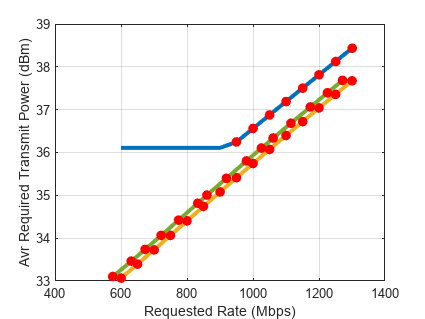

P_t_NA_16_dbm = 10*log10(P_t_NA_16) + 30;
P_t_NA_32_dbm = 10*log10(P_t_NA_32) + 30;
P_t_NA_64_dbm = 10*log10(P_t_NA_64) + 30;

% x_axis = [rate_req_arr(1) rate_16] ./ 1e6;
% plot(x_axis, [P_t_NA_16_dbm, P_t_NA_16_dbm], "DisplayName", 'Non-adaptive Scheme, M = 16', 'LineWidth', 2)
% 
% x_axis = [rate_req_arr(1) rate_32] ./ 1e6;
% plot(x_axis, [P_t_NA_32_dbm, P_t_NA_32_dbm], "DisplayName", 'Non-adaptive Scheme, M = 32', 'LineWidth', 2)
% 
% x_axis = [rate_req_arr(1) rate_64] ./ 1e6;
% plot(x_axis, [P_t_NA_64_dbm, P_t_NA_64_dbm], "DisplayName", 'Non-adaptive Scheme, M = 64', 'LineWidth', 2)
hold off

xlabel('Requested Rate (Mbps)')
ylabel('Avr Required Transmit Power (dBm)')
% legend()
grid on